# CT Segmentation

Team SPECT

Mei Li Luisa Cham Perez A01139386

---- A00

---- A00

---- A00

---- A00

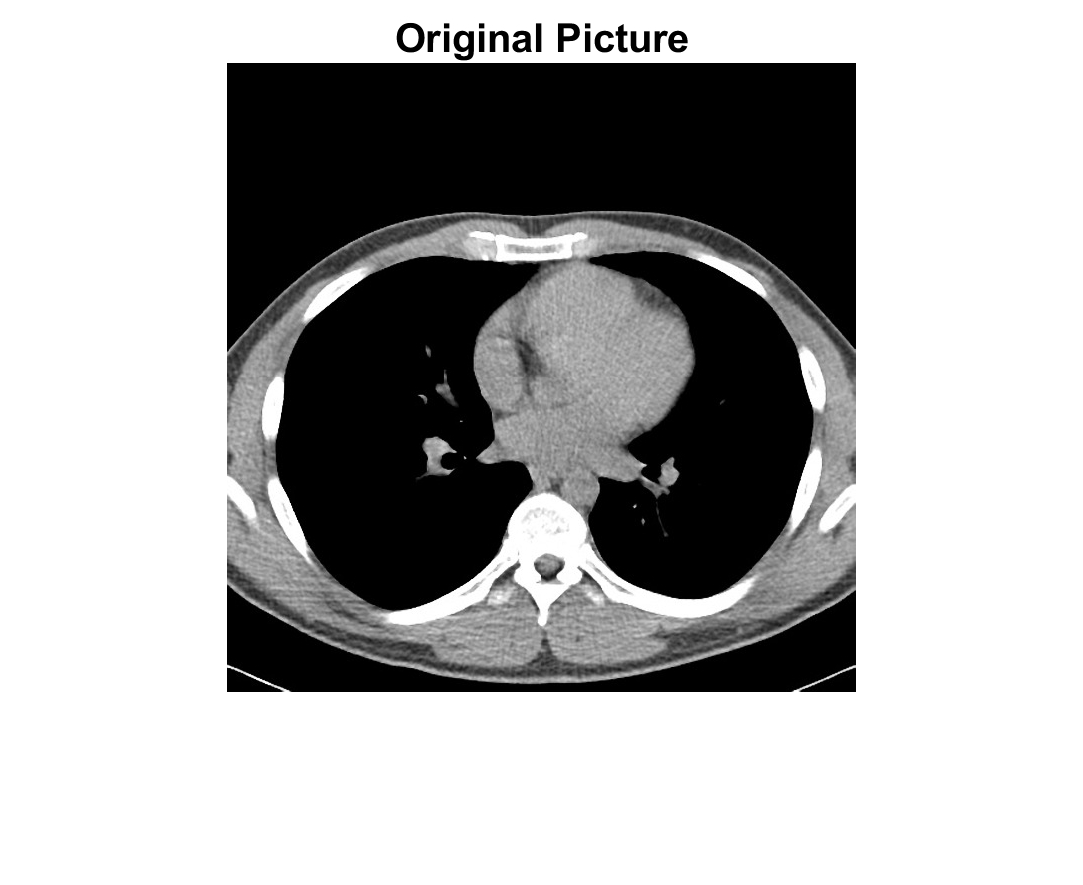

f=imread("CT_CHEST.jpeg");
f=double(f(:,:,1));
f=f/max(max(f));
imshow(f)
title('Original Picture')

## Otsu Segmentation

%Roberts Operator
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];

% Disk for clossing labels
diskse11= strel('disk',11);

thr = graythresh(f)         %define threshold 
seg1 = f > thr;             %
imshow(seg1,[])             %black and white image contrast that is placed under the original image 
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];  % gradiente en y


image_open = imopen(seg1,diskse11);
image_close = imclose(seg1,diskse11);

imshow(image_open)
title('Open Image')

imshow(image_close)
title('Close Image')

cc = bwconncomp(image_close == 0,4);
L = labelmatrix(cc);
imshow(L,[])
title('Label Matrix image')

% 6 for right lung, 7 for left lung
imshow(L == 6)
title('Right lung')

## K-means Segmentation

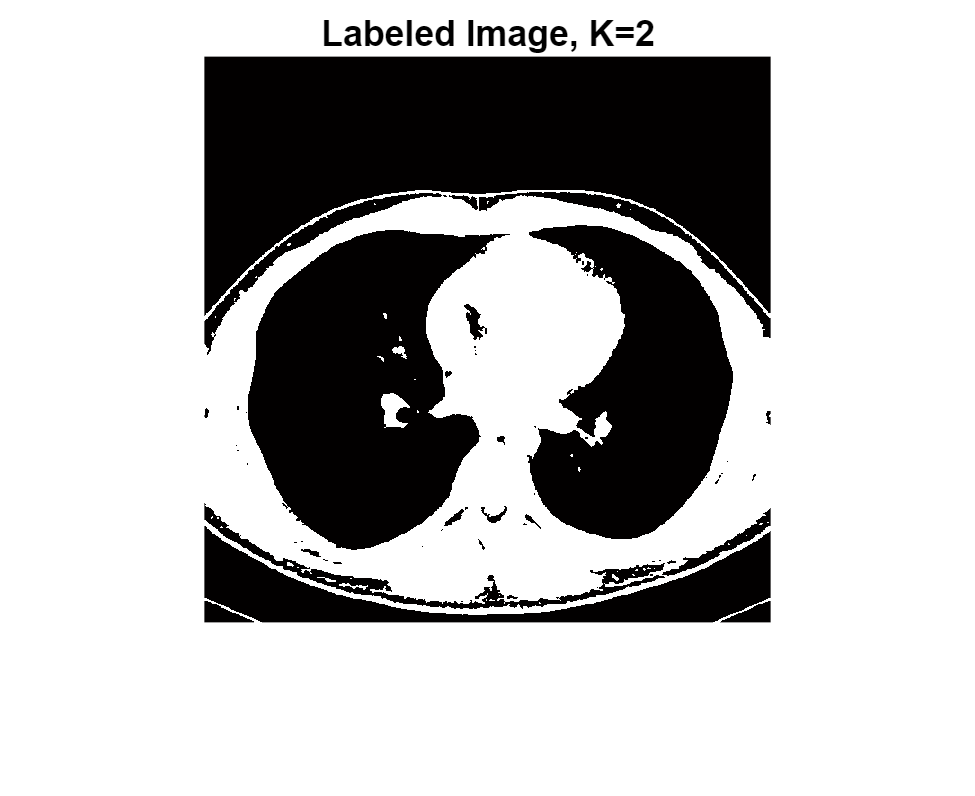

% 2 class
[L,Centers] = imsegkmeans(uint8(255*f),2);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=2")

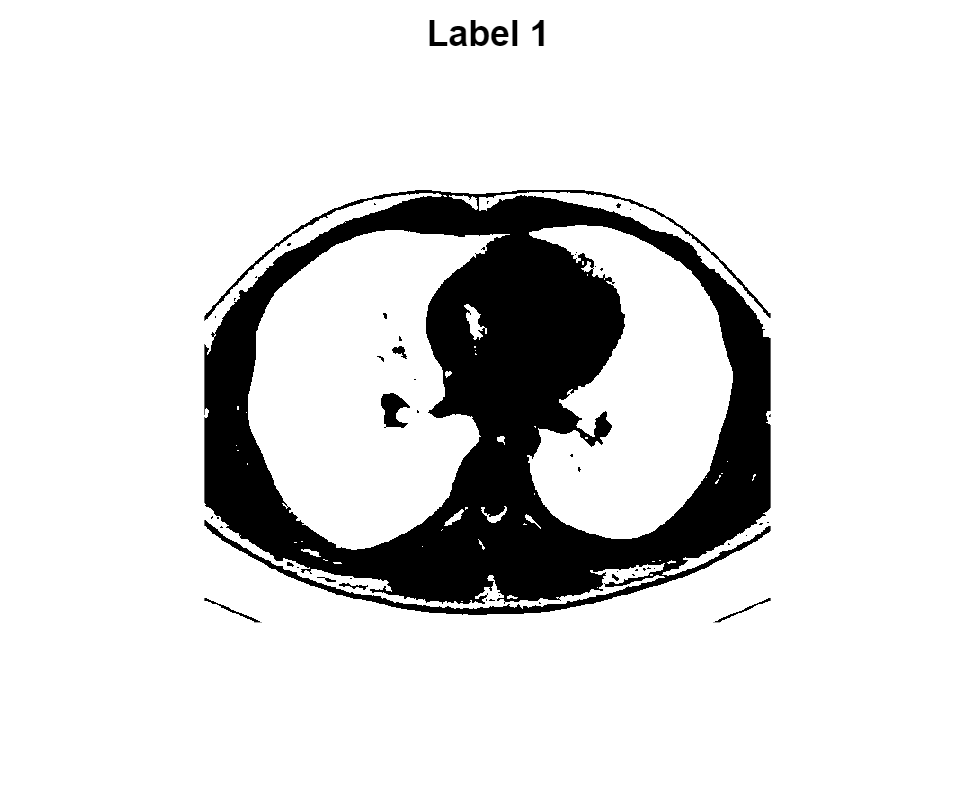



%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')

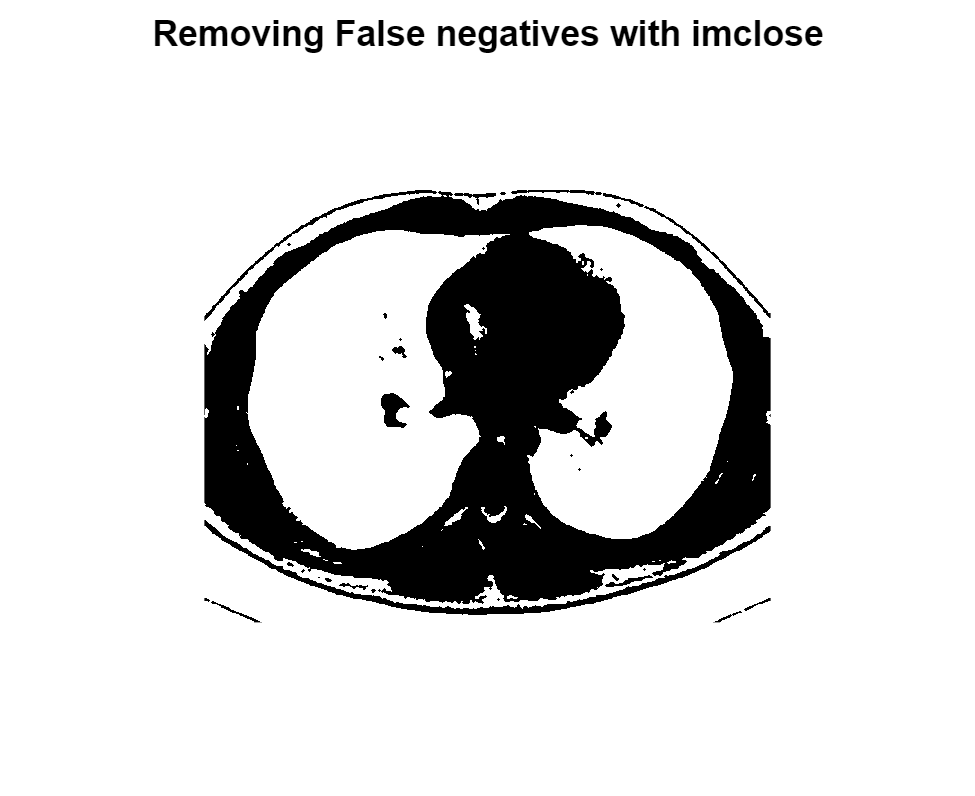

% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

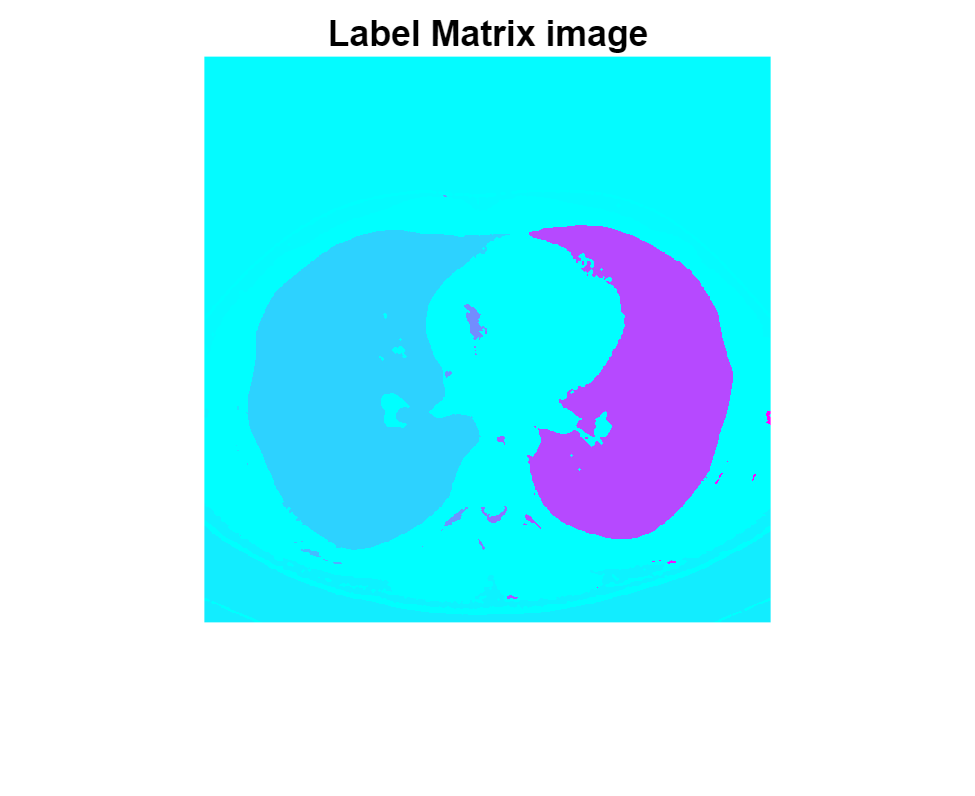



cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image')
colormap('cool')

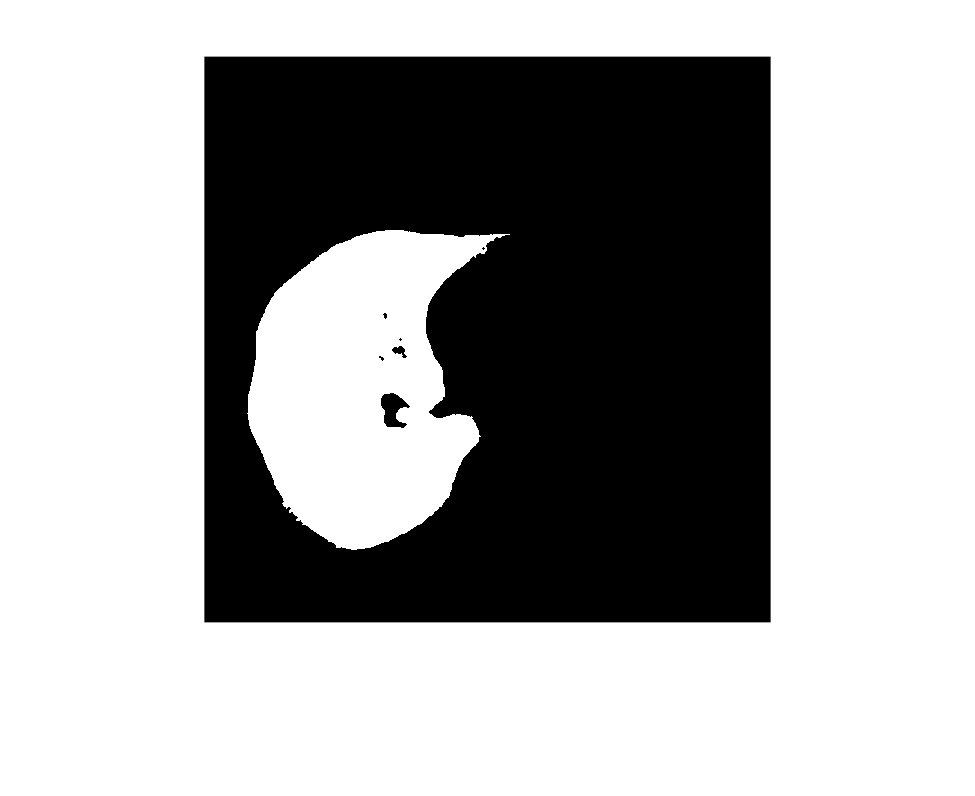

imshow(labeled == 10)    % 10 for right lung

title('Right lung, K=2')

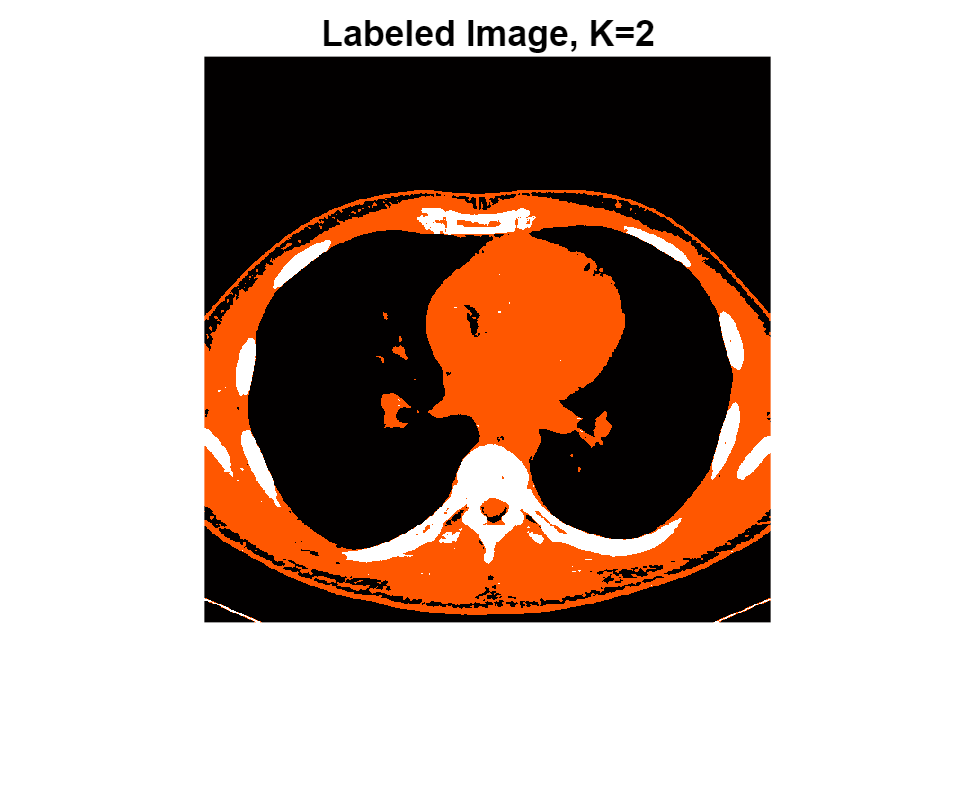

% 3 class
[L,Centers] = imsegkmeans(uint8(255*f),3);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=2")

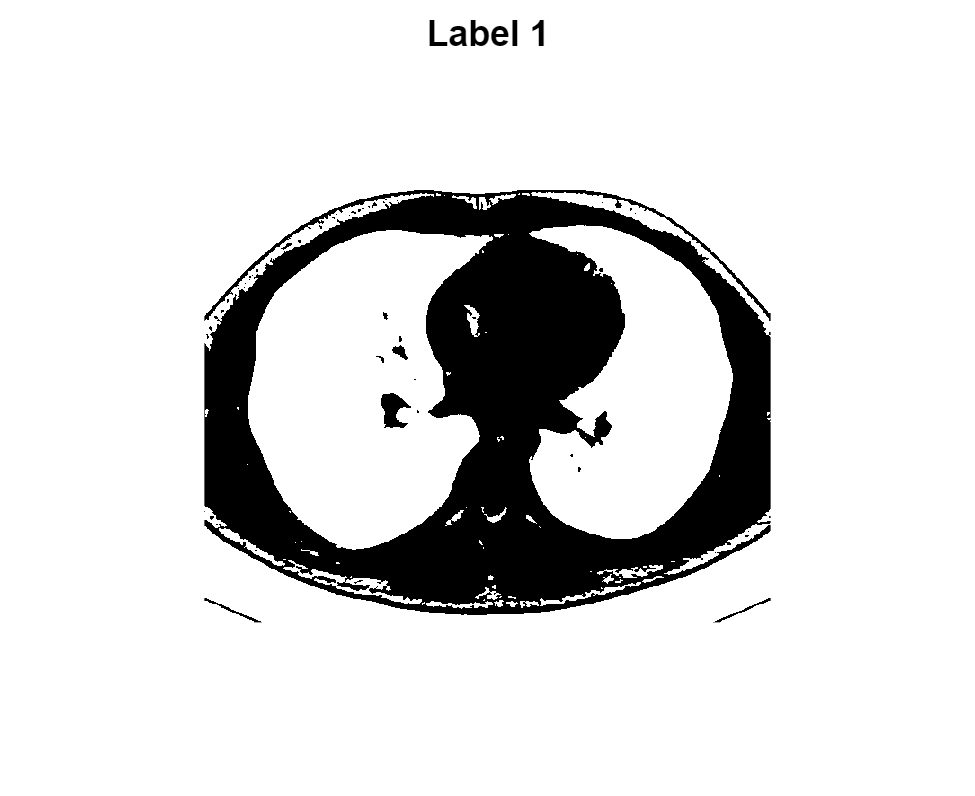


%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')

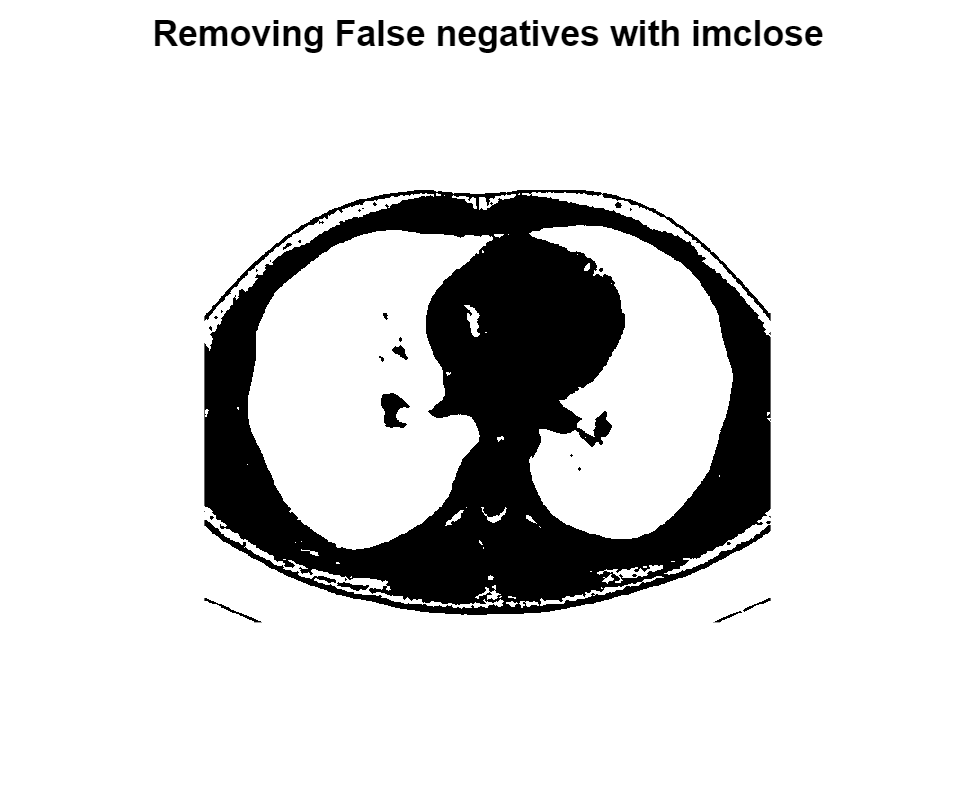

% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

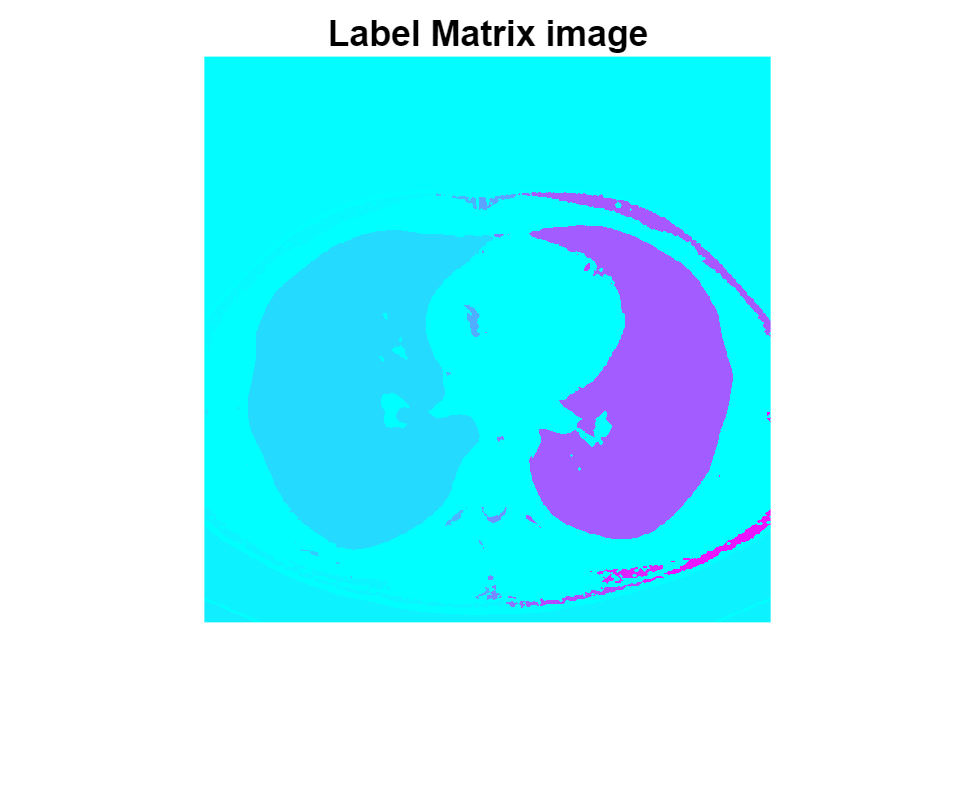


cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image')
colormap('cool')

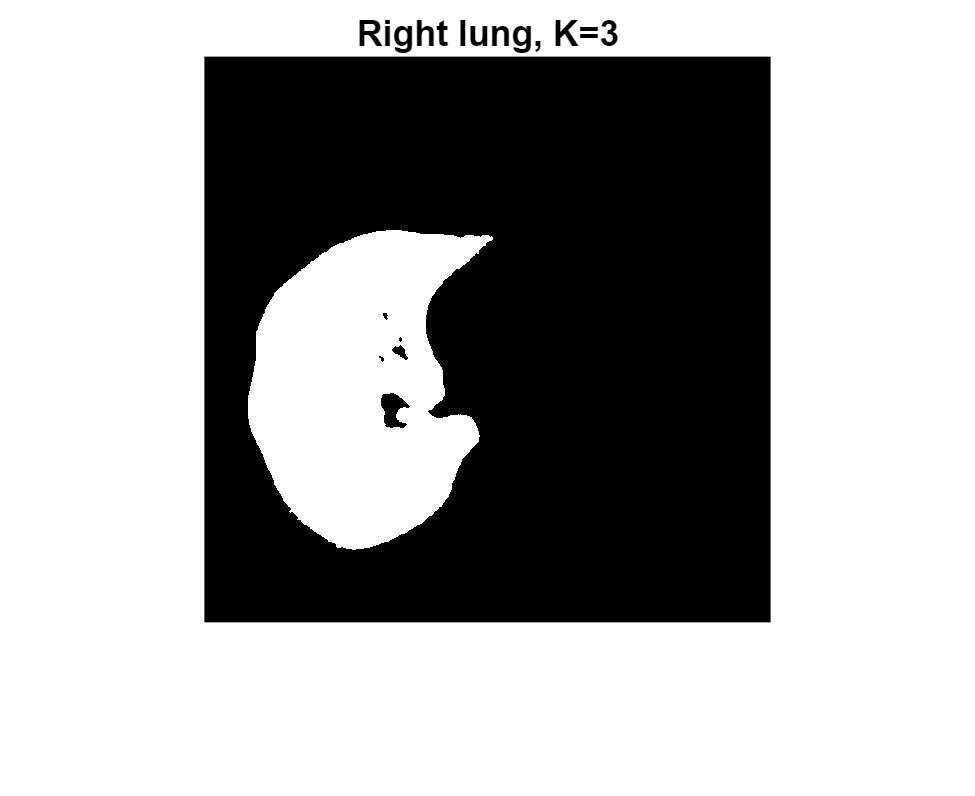

imshow(labeled == 11)    % 10 for right lung
title('Right lung, K=3')

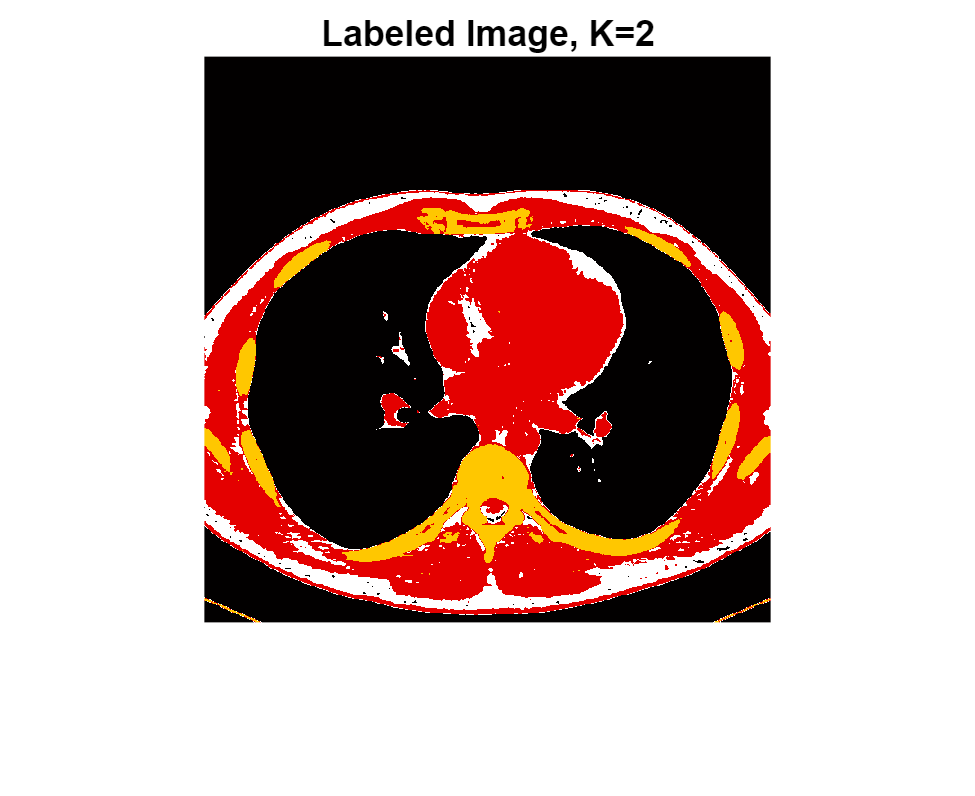

% 4 class
[L,Centers] = imsegkmeans(uint8(255*f),4);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image, K=2")

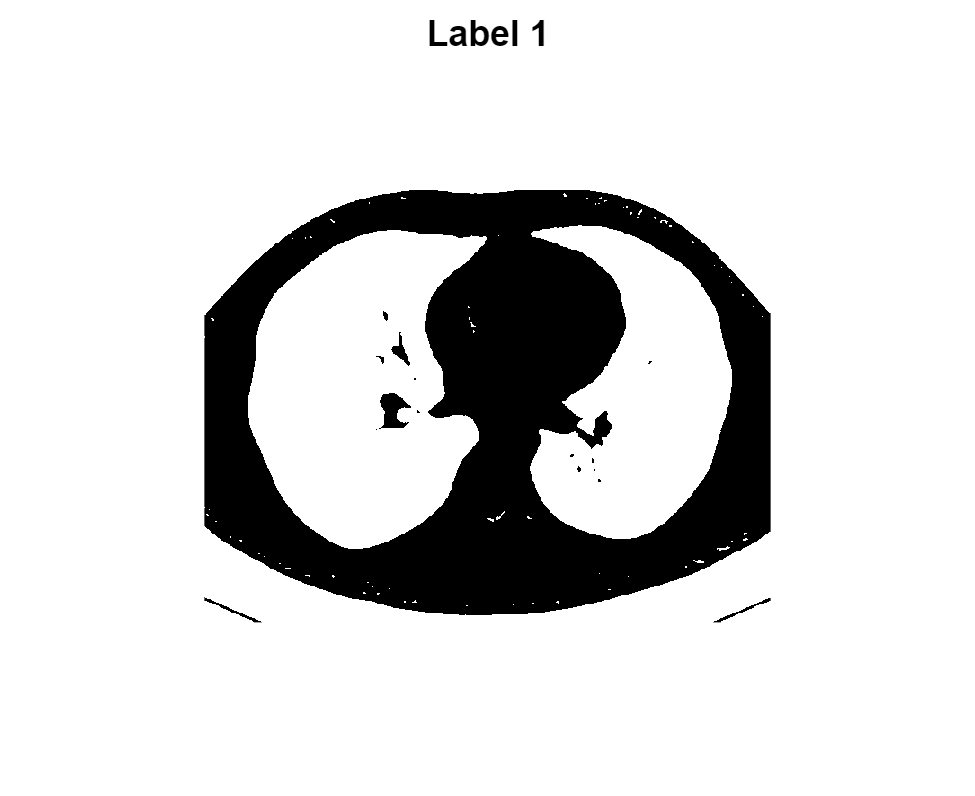


%First label
subplot(1,1,1)
label_one = L == 1;
imshow(label_one)
title('Label 1')

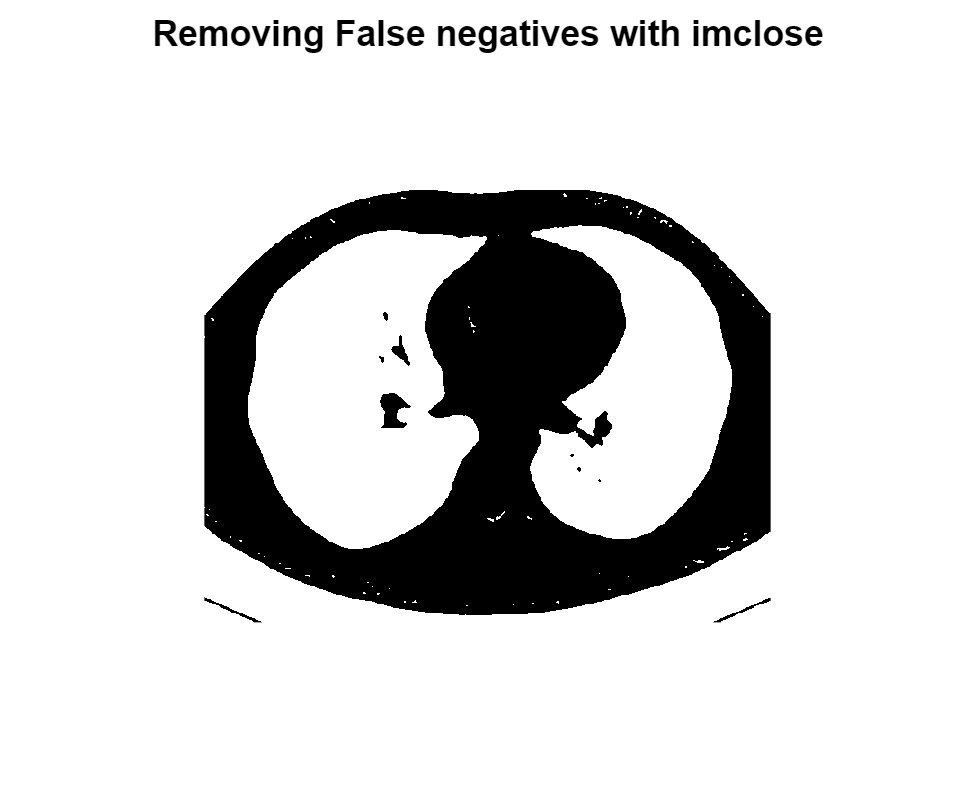

% remove false negatives wiht imclose
diskse = strel('disk',1);
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)
title('Removing False negatives with imclose')

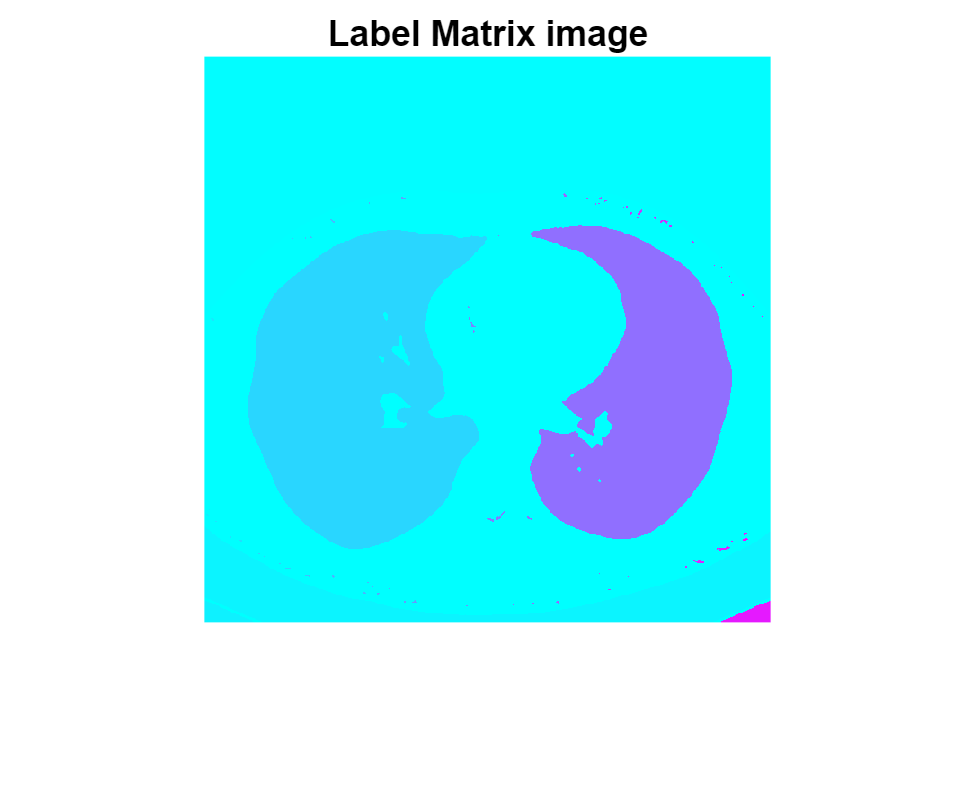


cc = bwconncomp(label_close_one,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
title('Label Matrix image')
colormap('cool')

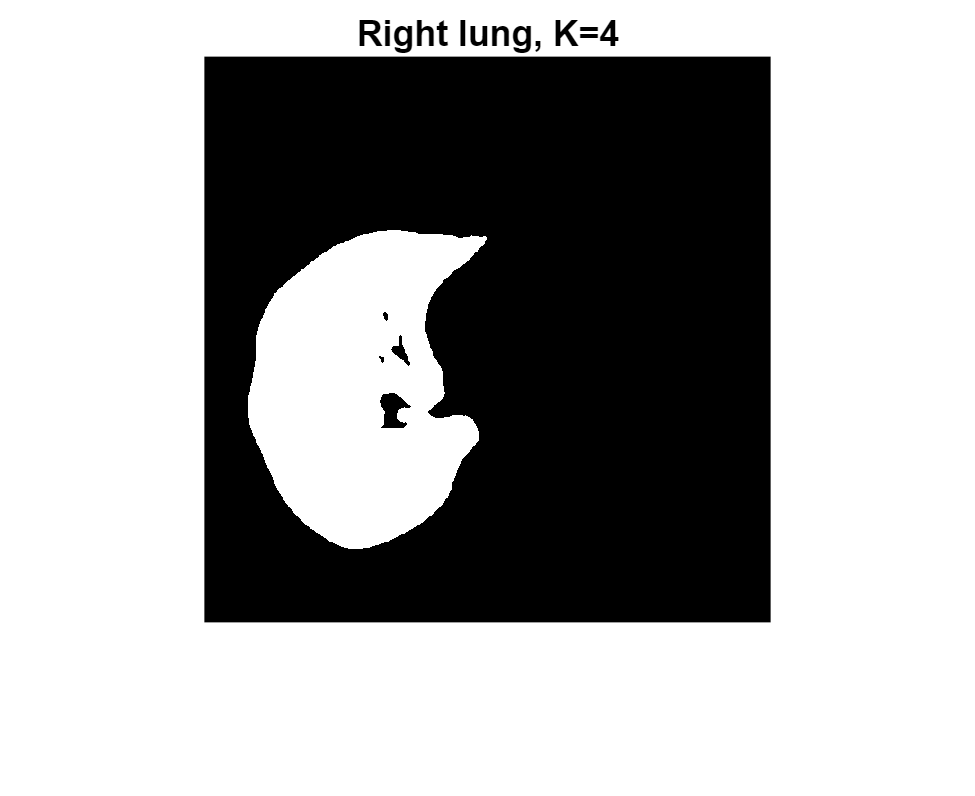

imshow(labeled == 14)    % 10 for right lung
title('Right lung, K=4')